%% Setup dir 
% raw data folder
selpath = uigetdir('C:\Users\Yingying\Desktop\','Select folder containing all scans');
segListing = dir(selpath);   
segListing(1:2) = []; % remove directory entries
% % shadow mask dir
% selpath2 = uigetdir(selpath,'store the shadow mask');
% segListing2 = dir(selpath2);   
% segListing2(1:2) = []; % remove directory entries
%% result dir
% store the result figures and matrix result and mask.
selpathout = uigetdir(selpath,'Select folder containing figure result');
% probe poisition (mannually set up)
n_scans = length(segListing);
% %07-28
name = '07-28';
number_of_probes = 3;
poisition_probe = cell(n_scans,1);
poisition_probe{1} = [168 604; 474 596; 836 668];
% poisition_probe{2} = [242 424;476 494;684 462;982 452];
poisition_probe{2} = [156 558; 424 600; 826 686];
% poisition_probe{3} = [200 632; 452 632; 872 672];
poisition_probe{3} = [214 546; 486 592; 850 640];
poisition_probe{4} = [172 562; 506 594; 864 656];
poisition_probe{5} = [200 554; 432 572; 868 646];
poisition_probe{6} = [170 542; 406 576; 860 674];
poisition_probe{7} = [190 526; 428 566; 832 664];
% 
fov_all = [1120 1120 1120 1120 1120 1120 1120 1120];
% vessel_ratio = [2 1.5 2 1.8 2 1.9 2];
vessel_ratio = [2 1.5 2 1.8 2 1.9 2];
number_of_site = 3;
legend_a = {"Baseline","1 w","2 Ws","3 Ws","4 Ws","5 Ws","6 Ws"};

% Read Files, crop Z and store the intensity distributation across Z
% variables in this section

ch_1_n_names = cell(n_scans,1);   % store the name of the file
ch_2_n_names = cell(n_scans,1);

Ch_1_raw = cell(n_scans,1);       % store the raw results
Ch_2_raw = cell(n_scans,1);

% record the intensity per scan  - > draw the intensity figures
result_c1intensity = cell(n_scans,1);
result_c2intensity = cell(n_scans,1);
result_c2intensity_crop = cell(n_scans,1);


% Vq = interp2(X,Y,V,Xq,Yq)
[Xn,Yn] = meshgrid(1:512);
dz = 511/1023;
[Xq,Yq] = meshgrid(1:dz:512);


% read files
for i = 1:n_scans
    % read channel 2
    file_name = segListing(i).name;
    ch_2_n_names{i} = file_name;
    filePath = fullfile(segListing(i).folder,file_name);
    Data = bfOpen3DVolume(filePath);
    RawData=Data{1,1}{1,1};
    [x,y,z] = size(RawData);
%     RawData = single(RawData);
  
    Ch_2_raw{i} = RawData;
end

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ..........................................................
Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................
Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    .............................................................
Reading series #1
    ........................................................................


% set up the parameters 
% fov_all = [1400 1400 1400 1120 1120 1120 1120];
width =500;
width_y = 100;
 

% Store the X AND Y crop result
Crop_C2data = cell(number_of_site,n_scans,2);
% Crop regions
for i = 1:n_scans
    fov = fov_all(i);
    dx = fov/1024;
    width_pixel = floor(width/(dx*2));
    size_pixel = width_pixel*2+1;
    widthy_pixel = floor(width_y/(dx*2));
    sizey_pixel = widthy_pixel*2+1;
    poisitions = poisition_probe{i};
    temp_data = Ch_2_raw{i};
    [x , y, z] = size(temp_data);
    for j = 1:number_of_site
        temp_poisitions = poisitions(j,:);
        temp_x = temp_poisitions(1);
        temp_y = temp_poisitions(2);
        % X
        temp_c2data = zeros(sizey_pixel,size_pixel,z);
        for p = 1:z
            for m = 1:size_pixel
                for n = 1:sizey_pixel
                    index_x = temp_y-widthy_pixel+n-1;
                    index_y = temp_x-width_pixel+m-1;
                    if index_x > 0 && index_x < (x+1) && index_y > 0 && index_y < (y+1)
                        temp_c2data(n,m,p) = temp_data(temp_y-widthy_pixel+n-1,temp_x-width_pixel+m-1,p);
                    else
                        temp_c2data(n,m,p) = -100;
                    end
%                     temp_c2data(n,m,p) = temp_data(temp_y+n-1,temp_x-width_pixel+m-1,p);
%                     temp_c2data(n,m,p) = temp_data(temp_y-widthy_pixel+n-1,temp_x+m-1,p);
                end
            end
        end
%         outputFileName = [selpathout '\Poisition_' num2str(j) '_CropX_' ch_1_n_names{i}];
%         if exist(outputFileName)
%             delete(outputFileName);
%         end
%         for p=1:z
%             temp_slice = temp_c2data(:,:,p);
%             imwrite(temp_slice, outputFileName, 'WriteMode', 'append',  'Compression','none');
%         end
        Crop_C2data{j,i,1} = temp_c2data;
        % Y
        temp_c2data = zeros(sizey_pixel,size_pixel,z);
        for p = 1:z
            for m = 1:size_pixel
                for n = 1:sizey_pixel
                    index_x = temp_y-width_pixel+m-1;
                    index_y = temp_x-widthy_pixel+n-1;
                    if index_x > 0 && index_x < (x+1) && index_y > 0 && index_y < (y+1)
                        temp_c2data(n,m,p) = temp_data(index_x,index_y,p);
                    else
                        temp_c2data(n,m,p) = -100;
                    end
%                     temp_c2data(n,m,p) = temp_data(temp_y+n-1,temp_x-width_pixel+m-1,p);
%                     temp_c2data(n,m,p) = temp_data(temp_y-widthy_pixel+n-1,temp_x+m-1,p);
                end
            end
        end
%         outputFileName = [selpathout '\Poisition_' num2str(j) '_CropY_' ch_1_n_names{i}];
%         if exist(outputFileName)
%             delete(outputFileName);
%         end
%         for p=1:z
%             temp_slice = temp_c2data(:,:,p);
%             imwrite(temp_slice, outputFileName, 'WriteMode', 'append',  'Compression','none');
%         end
        Crop_C2data{j,i,2} = temp_c2data;
    end
end

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

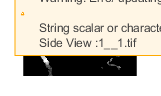

Direction : Y


ratio = 1

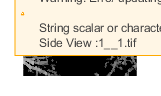

Probe Poisition : 2


Direction : X


ratio = 1

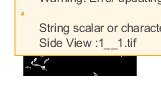

Direction : Y


ratio = 1

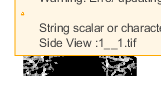

Probe Poisition : 3


Direction : X


ratio = 1

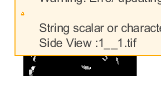

Direction : Y


ratio = 1

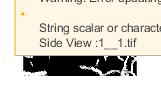

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

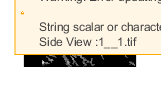

Direction : Y


ratio = 1

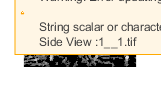

Probe Poisition : 2


Direction : X


ratio = 1

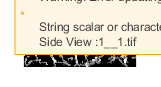

Direction : Y


ratio = 1

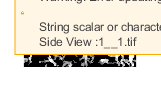

Probe Poisition : 3


Direction : X


ratio = 1

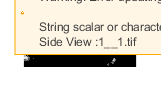

Direction : Y


ratio = 1

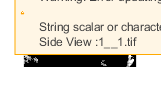

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

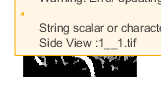

Direction : Y


ratio = 1

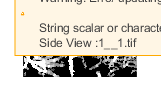

Probe Poisition : 2


Direction : X


ratio = 1

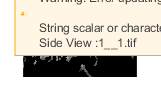

Direction : Y


ratio = 1

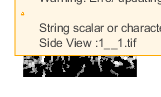

Probe Poisition : 3


Direction : X


ratio = 1

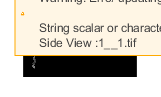

Direction : Y


ratio = 1

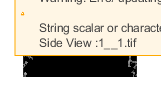

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

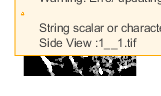

Direction : Y


ratio = 1

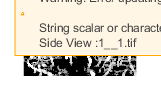

Probe Poisition : 2


Direction : X


ratio = 1

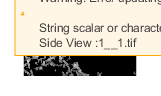

Direction : Y


ratio = 1

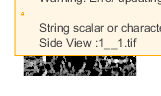

Probe Poisition : 3


Direction : X


ratio = 1

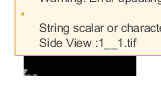

Direction : Y


ratio = 1

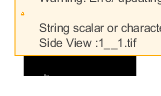

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

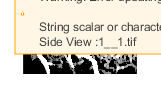

Direction : Y


ratio = 1

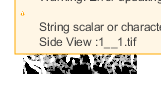

Probe Poisition : 2


Direction : X


ratio = 1

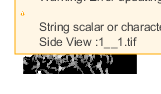

Direction : Y


ratio = 1

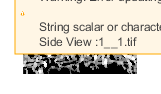

Probe Poisition : 3


Direction : X


ratio = 1

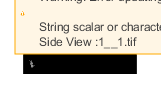

Direction : Y


ratio = 1

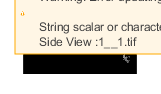

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

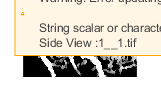

Direction : Y


ratio = 1

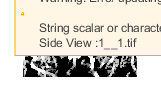

Probe Poisition : 2


Direction : X


ratio = 1

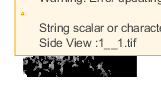

Direction : Y


ratio = 1

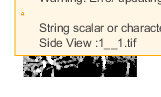

Probe Poisition : 3


Direction : X


ratio = 1

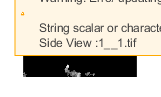

Direction : Y


ratio = 1

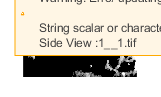

--------------------


Probe Poisition : 1


Direction : X


ratio = 1

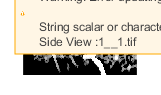

Direction : Y


ratio = 1

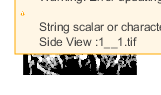

Probe Poisition : 2


Direction : X


ratio = 1

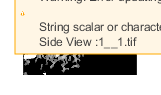

Direction : Y


ratio = 1

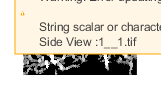

Probe Poisition : 3


Direction : X


ratio = 1

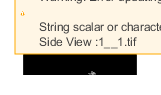

Direction : Y


ratio = 1

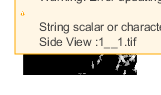

% % Set up contrast and draw figures
low_limit =0.005;
high_limit = 0.5;
 
z_constant = 200;
XY_poisition = {'X','Y'};
diameter_results = zeros(size_pixel,n_scans*number_of_site*2);
variance_results = zeros(size_pixel,n_scans*number_of_site*2);
for i = 1:n_scans
    disp(['---------' ch_1_n_names{i} '-----------'])
    for j = 1:number_of_site
        disp(['Probe Poisition : ' num2str(j)])
        for n = 1:2
            index = (i-1)*number_of_site*2+(j-1)*2+n;
            disp(['Direction : ' XY_poisition{n}])
            temp_data = Crop_C2data{j,i,n};
            ratio = 1%vessel_ratio(i);
            temp_data = temp_data/ratio;
            [x y z] = size(temp_data);
            % draw MIP figure
            if z>z_constant
                [diameter_results(:,index),variance_results(:,index)] = New_IP(temp_data(:,:,51:z_constant));
            else
                [diameter_results(:,index),variance_results(:,index)] = New_IP(temp_data(:,:,51:z));
            end
%             diameter_results(:,index)= temp_fig_processed;
            % draw side view figures
            temp_fig_processed = squeeze(max(temp_data,[],1));
            temp_fig_processed = temp_fig_processed/max(temp_fig_processed(:));
%             curfig = figure();  
            curfig = figure();
            imshow(imadjust(temp_fig_processed',[low_limit high_limit]))
            % colormap('jet')
            title(['Side View :' ch_2_n_names{2}])
            outputFileName = [selpathout '\Side_Poisition_' num2str(j) '_Crop_' XY_poisition{n} '_' ch_2_n_names{i}];
            saveas(curfig,outputFileName);
        end
    end
end